# Predicción de la radiación solar

Esta demostración crea y prueba un modelo basado en la temperatura y la humedad para estimar la radiación solar global media diaria. A medida que la radiación del sol penetra en la atmósfera, una parte de la radiación se dispersa, refleja o absorbe. La cantidad que llega a la superficie terrestre (ya sea directamente o a través de la dispersión) se conoce como **radiación solar global**. La temperatura máxima diaria, la **temperatura mínima** diaria y la **humedad media diaria **se utilizan para estimar la relación de la radiación solar global con la radiación extraterrestre (es decir, la relación entre la cantidad de radiación que llega a la superficie de la Tierra y la que llega a la parte superior de la atmósfera).

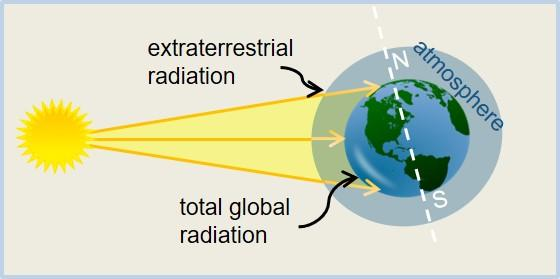

## Leamos los datos de un archivo de Excel

Datos modificados a partir de los obtenidos en Davis, CA de 2001 a 2010 por el Sistema de Información de Gestión del Riego de California, Departamento de Recursos Hídricos.([http://www.cimis.water.ca.gov/cimis/data.jsp](http://www.cimis.water.ca.gov/cimis/data.jsp))

Utilizaremos el [Import Tool](https://la.mathworks.com/help/matlab/ref/importtool.html) para importar los datos del archivo **DavisDaily.xlsx**. Seleccionaremos las columnas `Date`, `DayofYear`, `SolRatio`, `MaxAirTemp`, `MinAirTemp `y` AvgRelHum`.

Generaremos una función y la guardaremos como `ImportData`, que utilizaremos para leer los datos.

Podemos explorar los datos de diferentes maneras, por ejemplo, generando un resumen de las columnas

## Exploremos los datos gráficamente

Para ello, utilizaremos una Live Task llamada **Create Plot. **

## Podemos extraer información de la tabla para realizar otros análisis

La relación de la radiación solar global no es constante. Varía a lo largo del año y también de un año a otro. Puede variar significativamente dependiendo de las condiciones meteorológicas locales y de la estación. La refracción y atenuación de la energía solar es causada por procesos complejos relacionados con la cobertura de nubes, el contenido de humedad y otras impurezas atmosféricas.

## Visualicemos cómo varía la relación entre la radiación solar global y la radiación extraterrestre durante el año y a través de diferentes años

Utilizaremos nuevamente la Live Task **Create Plot **para agregar más información a nuestro gráfico.

La temporada de lluvias para Davis es desde finales de otoño hasta principios de primavera (octubre a abril -- aproximadamente día del año, 1-91 y 274-365) 

## Reservamos datos para pruebas

Reservamos un conjunto de datos que se utilizará más tarde para probar nuestra estimación. Construimos nuestro modelo con los datos restantes. En este caso, elegimos un conjunto en el medio de nuestro conjunto de datos, el año 2006. Para ello, utilizaremos [indexado con valores lógicos](https://la.mathworks.com/help/matlab/math/array-indexing.html#MatrixIndexingExample-3).

También necesitaremos calcular $ \Delta T = T_{DailyMax} - T_{DailyMin} $. Y lo guardamoos en  **Data.delT**

Separaremos los datos para ajustar nuestra fórmula:

my_delT = Data.delT(idx);

Data = 3652×6 table
       Date        DayofYear    SolRatio    MaxAirTemp    MinAirTemp    AvgRelHum
    ___________    _________    ________    __________    __________    _________
    01-Jan-2001        1          0.64         60.9          30.2          85    
    02-Jan-2001        2          0.66         55.5          25.8          92    
    03-Jan-2001        3          0.67         65.2          29.6          76    
    04-Jan-2001        4          0.67         62.6          26.9          76    
    05-Jan-2001        5          0.67           64          27.6          74    
    06-Jan-2001        6          0.59         61.8          30.5          82    
    07-Jan-2001        7          0.29         50.6          31.5          86    
    08-Jan-2001        8           0.2

my_AvgRelHum = Data.AvgRelHum(idx);
my_SolRatio = Data.SolRatio(idx);
my_DayofYear = Data.DayofYear(idx);

Data: 3652×6 table
Variables:
    Date: datetime
    DayofYear: double
    SolRatio: double
    MaxAirTemp: double
    MinAirTemp: double
    AvgRelHum: double
Statistics for applicable variables:
                  NumMissing          Min                   Median                   Max                    Mean                    Std      
    Date               0          01-Jan-2001        31-Dec-2005 12:00:00        31-Dec-2010        31-Dec-2005 12:00:00        25305:15:43  
    DayofYear          0                    1                         183                366                    183.1002           105.4386  
    SolRatio          14               0.0300                      0.6400                  1             

## Ajustamos la fórmula a los datos

La siguiente fórmula se utiliza para predecir la relación entre la radiación solar global y la radiación extraterrestre como función de las variaciones diarias de temperatura y la humedad relativa. La siguiente fórmula describe el comportamiento a gran escala, y es similar a las utilizadas en otros estudios. Esta demostración se centra en el flujo de trabajo y no en la ecuación específica utilizada.


$$R_s = a*(1-b*H)*(1 - e^{(-c (\Delta T)^n)})$$


Para ello usaremos una interfaz gráfica llamada [Curve Fitter](https://la.mathworks.com/help/curvefit/curvefitter-app.html), donde podremos explorar diferentes opciones de ajustes de curvas

Explora diferentes tipos de ajustes

Copia la siguiente ecuación en la opción de **Custom Equation **y cambia los valores de X y Y

Para ejecutar la función que hemos creado, podemos usar el siguiente código:


disp(model)

## Estimamos el valor de la relación entre la radiación solar global y la radiación extraterrestre

Data = 3652×8 table
       Date        DayofYear    SolRatio    MaxAirTemp    MinAirTemp    AvgRelHum    Year    delT
    ___________    _________    ________    __________    __________    _________    ____    ____
    01-Jan-2001        1          0.64         60.9          30.2          85        2001    30.7
    02-Jan-2001        2          0.66         55.5          25.8          92        2001    29.7
    03-Jan-2001        3          0.67         65.2          29.6          76        2001    35.6
    04-Jan-2001        4          0.67         62.6          26.9          76        2001    35.7
    05-Jan-2001        5          0.67           64          27.6          74        2001    36.4
    06-Jan-2001       

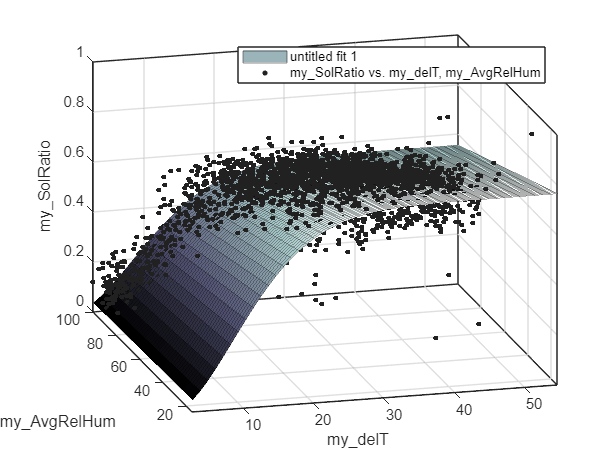

     General model:
     model(delT,H) = a*(1-b*H)*(1-exp(-c*(delT)^n))
     Coefficients (with 95% confidence bounds):
       a =      0.7995  (0.786, 0.8129)
       b =    0.003052  (0.002777, 0.003328)
       c =     0.01015  (0.007715, 0.01258)
       n =       1.757  (1.666, 1.847)


EstRad = model(Data.delT(~idx), Data.AvgRelHum(~idx));
myErr = Data.SolRatio(~idx) - EstRad;
PredInt = predint(model,[Data.delT(~idx) Data.AvgRelHum(~idx)]);

*Copyright 2025 The MathWorks, Inc.*